clear all;
close all;
clc;
%Torrey Pines buoy correlation
%start time is July 02 2020 00:00:00
startTime = 20200702000000;
%end time is July 09 2020 18:00:00
endTime = 20200709180000;
%load glider data
gliderTable = readtable('metbuoy_19-04.csv');
%get waveglider time and wind vectors for appropriate times
[wgt wgWind10m ~] = gliderTime(gliderTable, startTime, endTime);
%upload san nic band frequency table
freqTable = readtable('Torrey_Pines_July2020.txt');

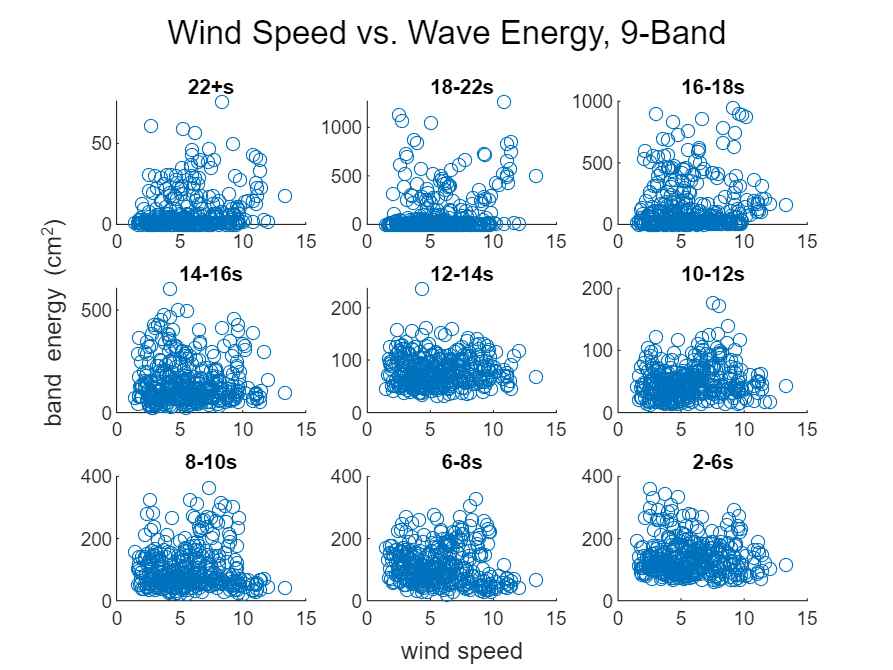

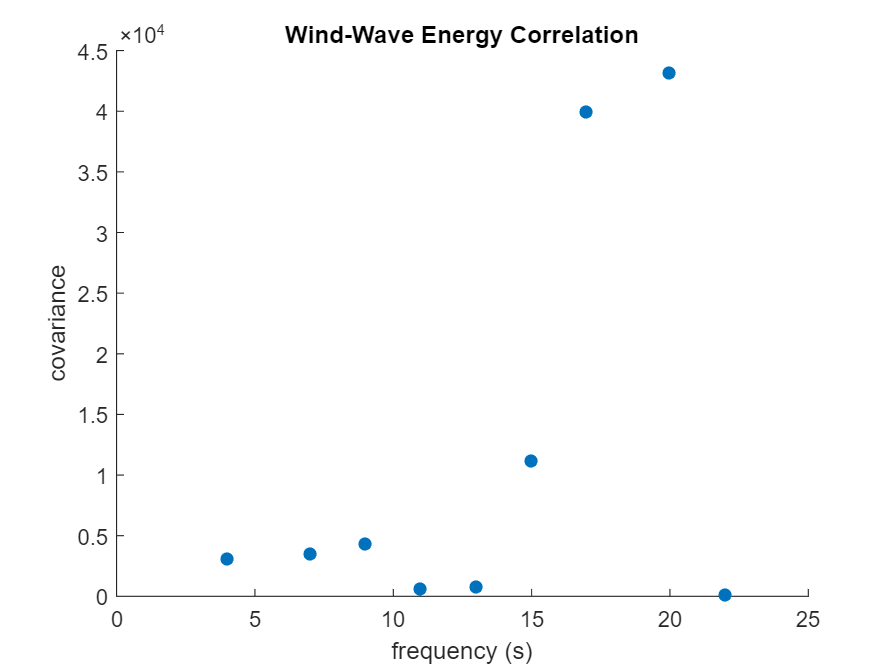

%correlation
windWaveCorr(freqTable, startTime, endTime, wgt, wgWind10m)